mic_calib = 0.8969

mic_calib = 0.8969

piezo_calib = 0.1596

piezo_calib = 0.1596

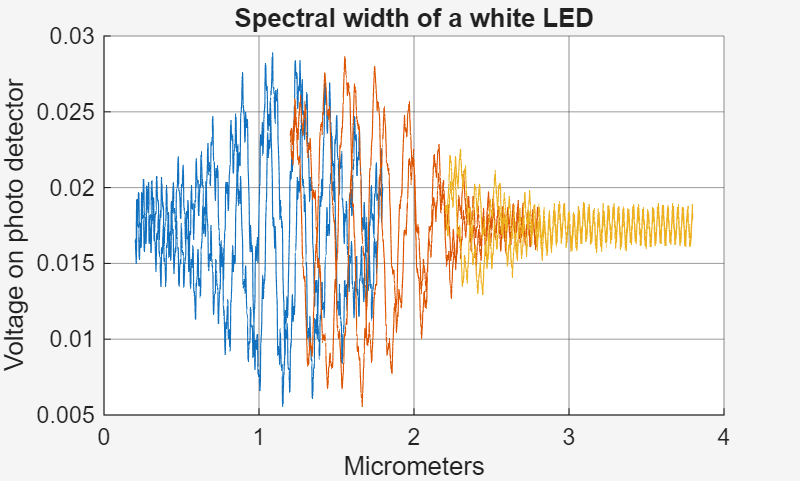


slice = readtable("Task9_16.txt");
time1 = slice.Var4;
detector1 = slice.Var5;
position1 = slice.Var10 * piezo_calib + 1;

slice = readtable("Task9_17.txt");
time2 = slice.Var4;
detector2 = slice.Var5;
position2 = slice.Var10 * piezo_calib + 2;

slice = readtable("Task9_18.txt");
time3 = slice.Var4;
detector3 = slice.Var5;
position3 = slice.Var10 * piezo_calib + 3;

figure;
hold on;
plot(position1, detector1)
plot(position2, detector2)
plot(position3, detector3)
title("Spectral width of a white LED")
xlabel("Micrometers")
ylabel("Voltage on photo detector")
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'white_led_spectral_width.png', 'Resolution', 300)